b = -0.046621;
y1 = -0.082201;
x1 = 0.5;

y = a* x + b 

(y-b) /x = a

a = (y1 - b)/x1;

Podstawienie rzeczywistych danych:

lambda = 0.195;
dmc0  = a*lambda + b 

dmc0 = -0.0605

## Cm_0W

AR = 7.844; %- 
wing_sweep025_deg = 30.484; %deg
wing_sweep025_rad = degtorad(wing_sweep025_deg);
epsilon_w = 2; %deg
cm0r = 0 

cm0r = 0

cmot = 0

cmot = 0


cm0w = AR*cos(wing_sweep025_rad)^2/(AR + 2* cos(wing_sweep025_rad)^2)+ (cmot+cm0r)/2 + dmc0*epsilon_w

cm0w = 0.5034

## Cm_0B

alfa0w = 1.4; %deg
MAC = 22.9 ;%ft
S = 3106.390; %ft^2 
w_f= [8.4,14.84,16.45,16.46,16.46,16.46,16.46,16.46,16.46,16.28,14.19,9.64,5.18]; 
i_cl = [-6.33,-0.846,0.289,0,0,0,0,0,-0.633,-3.79,-3.638,-1.927,-1.379];
Delta_X_f = [10.66,10.5,10.5,10.5,10.5,16.6,16.6,11.5,11.5,11.5,11.5,11.5,11.63];

l_b= 155 %ft

l_b = 155

d_b_max = 17.8%ft

d_b_max = 17.8000


FitnessRatio  = l_b/d_b_max

FitnessRatio = 8.7079

Na podstawie fitness ratio odczytywane są dane z wykresu:

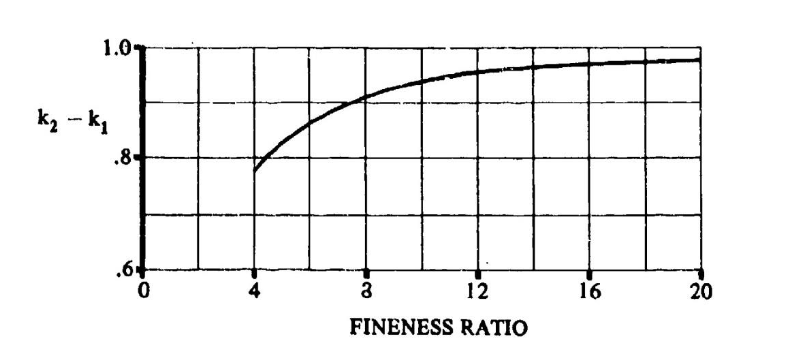

k1_k2 = 0.92355;
sum = 0;
for  i= 1:length(w_f)
    sum = sum + w_f(i)*deg2rad(alfa0w+i_cl(i))*Delta_X_f(i);
end
disp(sum)

   12.6704



    

cm0b = k1_k2/(36.5*S*MAC)*sum

cm0b = 4.5068e-06

## Cm_0WB

Należy odczytać wartość z wykresu

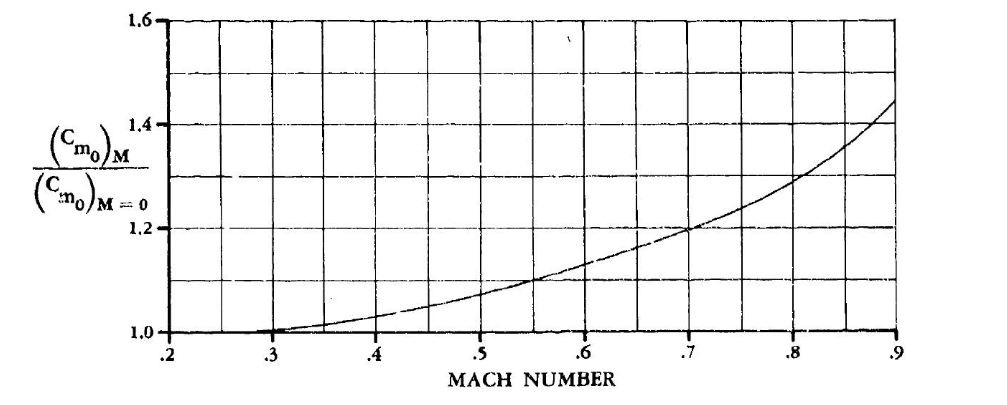

Cm0_ratio =[1.03074,1.0715,1.12919];
Cm0wb = (cm0b+cm0w).*Cm0_ratio

Cm0wb =     0.5189    0.5394    0.5685


Cl_afla_w  = [4.59,4.7452,4.9524];
CL_wb = Cl_afla_w*deg2rad(alfa0w)

CL_wb =     0.1122    0.1159    0.1210


Finalnie Cm0

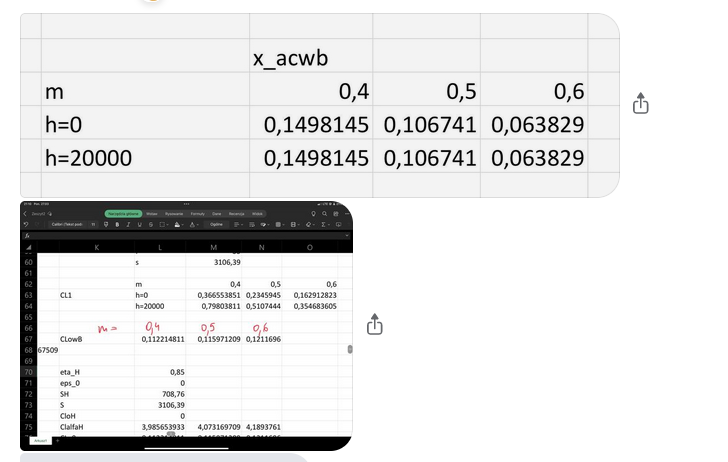

X_cg = 0.25;
x_ac_wb = [0.1498145,0.106741,0.063829];
 cm0 = Cm0wb + (X_cg-x_ac_wb).*CL_wb

cm0 =     0.5301    0.5560    0.5910


Cm_alfadot

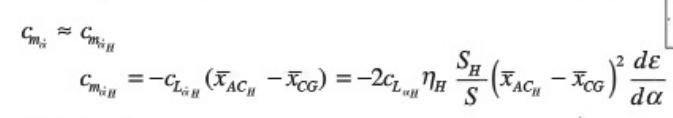

cl_alfa_h = [3.985654, 4.07317, 4.18938];
eta_h = 0.85;
Sh= 708.76;
S = 3106.39;
dedal= [0.2884 0.257497 0.21973];
xcg= 0.25;
x_whr= 79.6;
xmac= 20.414;
x_mac_h = 9.842;
mac_h = 12.669;
mac = 22.9;
x_ac_h=(x_whr-xmac+x_mac_h+mac_h/4)/mac;
cm_adot=-2 .*cl_alfa_h .*eta_h*(Sh/S) .*dedal*(x_ac_h-xcg)^2

cm_adot =    -3.7564   -3.4275   -3.0083


Wyznaczenie Cmih

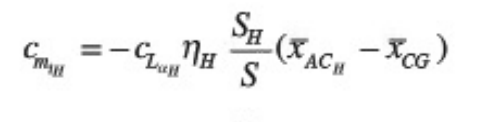

cmih= -cl_alfa_h*eta_h*(Sh/S)*(x_ac_h-xcg)

cmih =    -2.2436   -2.2929   -2.3583


CdQ

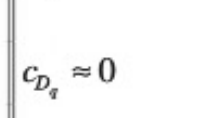

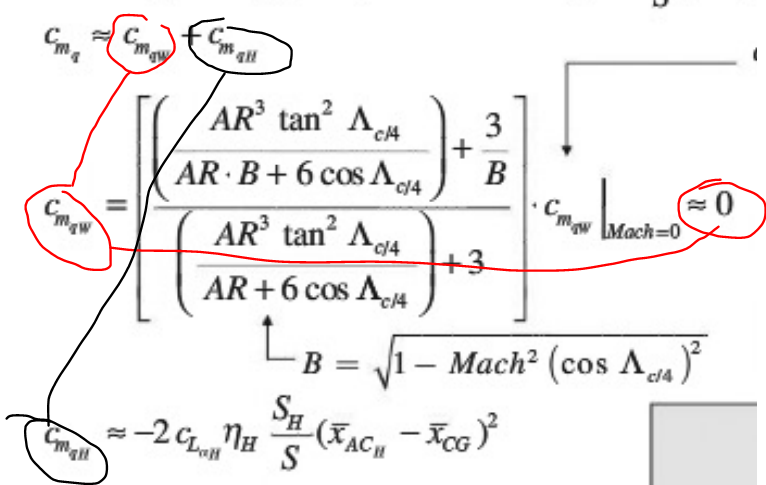

Wyliczamy Cmq

Cmq= -2*cl_alfa_h*eta_h*(Sh/S)*(x_ac_h-xcg)^2

Cmq =   -13.0249  -13.3109  -13.6907


Wyznaczenie clalfa_dot

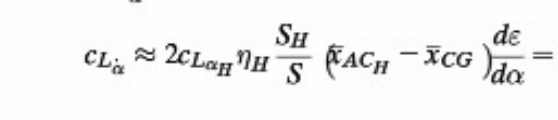

2*cl_alfa_h*eta_h*(Sh/S)*(x_ac_h-xcg) .* dedal

ans =     1.2941    1.1808    1.0364


Ale bym sobie Cl1 wyznaczyl

Q=270000

Q = 270000

density0 = 0.00237717;
density20k = 0.00126659;
speed0 = 1113.45;
speed20k= 1036.85;
V04=0.4*speed0;
V05=0.5*speed0;
V204=0.4*speed20k;
V206=0.6*speed20k;
q04= density0*(V04^2)/2

q04 = 235.7717

q05 = density0*(V05^2)/2

q05 = 368.3933

q204= density20k*(V204^2)/2

q204 = 108.9326

q206= density20k*(V206^2)/2

q206 = 245.0984

WS= Q/S

WS = 86.9176

C_l1= [WS/q04  WS/q05  WS/q204  WS/q206]

C_l1 =     0.3687    0.2359    0.7979    0.3546


a teraz alfa1

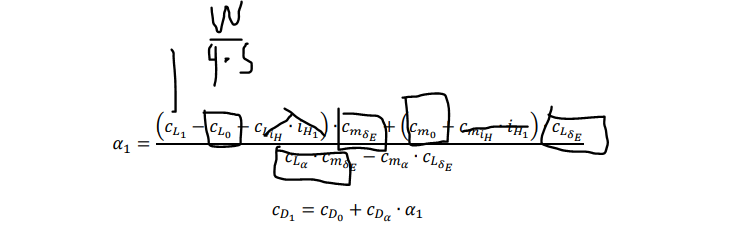

c_m_deltae=[ -0.8523 -0.871 -0.9131 -0.8958]

c_m_deltae =    -0.8523   -0.8710   -0.9131   -0.8958


c_l_deltae= [0.2937 0.3002 0.3147 0.3087]

c_l_deltae =     0.2937    0.3002    0.3147    0.3087


c_l_alfa= [5.4762 5.6729 5.4762 5.94154]

c_l_alfa =     5.4762    5.6729    5.4762    5.9415


c_m_0 = [0.5301 0.556 0.5301 0.591]

c_m_0 =     0.5301    0.5560    0.5301    0.5910


c_m_alfa = [-1.1359 -1.2265 -1.1355 -1.3426]

c_m_alfa =    -1.1359   -1.2265   -1.1355   -1.3426


c_l_0 = [0.12039 0.1243096 0.12039 0.12972]

c_l_0 =     0.1204    0.1243    0.1204    0.1297


alfa1= ((C_l1-c_l_0).*c_m_deltae + c_m_0 .*c_l_deltae)./(c_l_alfa .*c_m_deltae - c_m_alfa .* c_l_deltae)

alfa1 =     0.0129   -0.0152    0.0973    0.0039


Cd1 i Cxt1

Cd0=[0.012002 0.01205 0.012002 0.012120595];
Cd_alfa= [0.203643 0.135014 0.15654011 0.113855279];
Cd1= Cd0+Cd_alfa .* rad2deg(alfa1)

Cd1 =     0.1625   -0.1058    0.8848    0.0374


wyznaczenie de1

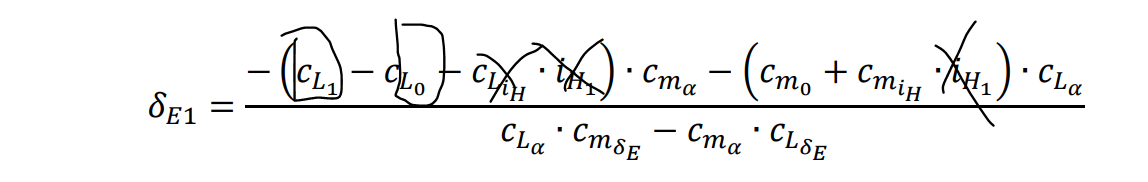

d_e1=(-(C_l1-c_l_0) .*c_m_alfa - (c_m_0).*c_l_alfa) ./(c_l_alfa.*c_m_deltae -c_m_alfa .* c_l_deltae)

d_e1 =     0.6048    0.6598    0.4595    0.6539
